## Decimal and Binary Representations

In the usual decimal representation, we can write any number $x$ as 


$$x=\sum_{i=-\infty }^{N} \beta_{i\text{ }} {10}^i$$
 

where the coefficients $\beta_i$ are values between 0 and 9. In binary representation the same number can be written as


$$x=\sum_{k=-\infty }^{M} \alpha_{k\text{ }} 2^k \ldotp$$


*Example 1*:  Write the number 37 in binary format. 

Let's start with the decimal representation. The number 37 can be written in decimal representation as $3\cdot {10}^1 +7\cdot {10}^0$, therefore in the above sum we can set $\beta_{0\text{ }} =7$ and $\beta_1 =3$. The number 37 can also be written as $3\ldotp 7\cdot {10}^1 \ldotp$

To find the binary representation of 37 we use repeated division by two. 

- 37 / 2 = 18 + 0.5 [1]

- 18 / 2 = 9 [0]

-   9 / 2 = 4 + 0.5 [1]

-   4 / 2 = 2 [0]

-   2 / 2 = 1 [0]

-   1 / 2 = 0 + 0.5 [1]

In the above list, we put a [0] if there is no remainder in the division or [1] if there is. Then we read the numbers in the brackets starting from the last and going up the list, finding ${100101}_2$. The binary number ${100101}_2$ can also be written as ${\left(\text{1 . 00101}\right)}_2 \cdot 2^5 \ldotp$ How and why does the algorithm work?

*Exercise 1*: Write the number 75 in binary representation and write it as ${\left(\text{1 . }d_1 d_2 d_3 d_4 d_5 d_6 \ldotp \ldotp \ldotp \right)}_2 \cdot 2^{\gamma } \ldotp$ 

**Answer**:  

(1.001011) x 2^6

*Example* 2:  Write the binary number ${101101}_2$ in decimal format.

This should be easy, simply expand the binary number representation: ${\mathrm{1 ⋅ 2 }}^5 {\mathrm{ + 0 ⋅ 2}}^4 +1\cdot 2^3 +1\cdot 2^2 +0\cdot 2^1 +1\cdot 2^0 =32+8+4+1=45$.

Similarly the number 45 is written in decimal representation as $4\cdot {10}^1 +5\cdot {10}^0$.

*Exercise 2*: Write the number ${1\ldotp 101010}_2 \cdot 2^6$ in decimal representation. 

**Answer**:  106

*Example* 3: Write the binary representation of the number 0.125.

We use the repeated multiplication algorithm.

- 0.125 * 2 = 0 + 0.25 [0]

- 0.25 * 2  =  0 + 0.5   [0]

- 0.5 * 2  = 1 + 0 [1]

if the multiplication gives a number greater or equal to 1 we  get a [1] otherwise we have a [0]. Then we read the numbers in the brackets from top to bottom: $0\ldotp 001=1\cdot 2^{-3}$. In fact using the binary representation, we have ${0\text{ ⋅ 2}}^0 {\text{+ 0 ⋅ 2}}^{-1} +0\cdot 2^{-2} +1\cdot 2^{-3} =0\ldotp 125$.

*Exercise 3*: Write the number 3.625 in binary representation. 

**Answer**:  (1.1101)2 x 2^1

## Floating Point Representations

Floating-point arithmetic was invented by Konrad Zuse in Berlin in the 1930s, and by the end of the 1950s it was standard across the computer industry. Until the 1980s, different computers had widely different arithmetic properties. Then, in 1985, after years of discussion, the Institute of Electrical and Electronics Engineers (IEEE) standard for binary floating-point arithmetic -- *IEEE arithmetic --*  was adopted. This standard has subsequently become nearly universal on processors of many kinds. 

A double precision number is stored using 64 bits, that is 64 numbers, where each of this number can be either 0 or 1. In particular, the 64 bits are subdivided in 3 sets: sign, exponent and mantissa.  For example, the machine representation of the number 1 in 64-bits is


$$\mathrm{0 }\text{ }\text{ }\text{ }\mathrm{01111111111}\text{ }\text{ } \text{ }0000000000000000000000000000000000000000000000000000\ldotp$$


Every number is stored as


$${\left(-1\right)}^{s\text{ }} \text{    }2^{c-1023} \text{   }{\left(1+f\right)}_2 \ldotp$$


The sign is defind by ${\left(-1\right)}^{s\text{ }}$.  Therefore to compute the sign we need only a single bit: if $s=0$ the number is positive, if $s=1$ the number is negative. The sign is the first bit in the 64-bits representation

The exponent $c$  is defined by the successive 11-bits. The largest binary number we can be represented with 11-bits is $2^{11} -1$=2047. Therefore the number defined by the exponent could range between 0 and 2047. In practice, to consider also negative exponents, the value is centered such $2^{-1023} \le 2^{c-1023} \le 2^{1024} \text{ }\ldotp$

The mantissa $f$ is then given by the remaining 52-bits and defines the number.

**A More Treatable Example**:

To better understand this representation let's consider a simplified example. Let's assume we have a 6-bits representation of a number. The first bit determines the sign, the following 3 bits  define the exponent and the last 2 the mantissa. The representation for the 6-bits number would look like this


$${\mathrm{( − 1)}}^s {\mathrm{    2}}^{c-3} \mathrm{   }\left(1+f\right) _2 .$$


The maximum exponent we can represent with 3 bits is given by $2^3 -1=7$. And therfore we center it, such that $2^{-3} \le a=2^{c-3} \le 2^4 \ldotp$ The number 1 can be represented as


$$0\text{   }011\text{ }\text{ }\text{ }\text{ }00\ldotp$$


The first bit is $s$, the following 3 bits represent $c$ and the final 2 bits represent the number $f$.

- The number $3$ can be written in binary representation as $3={11}_2 =1\ldotp 1_2 \cdot 2^1 =1\ldotp {10}_2 \cdot 2^1$. Therefore, by setting $c-3=1$, we find that $c=4={100}_2$ and finally 


$$0\text{    }100\text{  }10$$


- The smallest (in modulus) number we can represent is found by setting $c=0$ and $f=0\ldotp$ The representation $0\text{ }\text{ }\text{ }\text{ }000\text{ }\text{ }\text{  }00$, corresponds to the number ${\left(-1\right)}^0 2^{-3} \left(1+0\ldotp 00\right)=0\ldotp 125$.

- The maximum is found setting $c={111}_2 =7$ and $f={11}_2 =3$. The representation $0\text{   }111\text{ }\text{ }\text{ }\text{ }11$ corresponds to the number ${\left(-1\right)}^{s\text{ }} 2^4 {\left(1+0\ldotp 11\right)}_2 =1\ldotp {11}_2 \cdot 2^4 ={11100}_2 =28\ldotp$

- We cannot represent all the numbers between 0.125 and 28. In fact with a signed 6-bits representation we exactely represent only $2^6 -1=63$ numbers, and only $2^5 -1=31$ number with different absolute value. In particular

*Exercise 4*: Write the number 6-bit floating representation of the number 5 and  5/32=0.15625. 

**Answer**:  5 = 0 101 01; 5/32 = 0 000 01

*Exercise 5*: Plot on a line all the numbers represented by the 6-bit floating point representation.

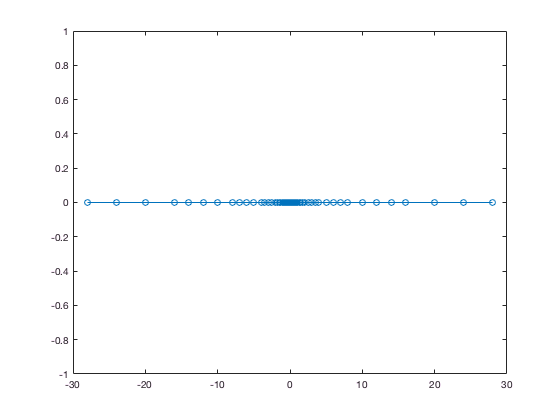

nums = [-1 -1.25 -1.5 -1.75 1 1.25 1.5 1.75];
fp = [1/8*nums 1/4*nums 1/2*nums 1*nums 2*nums 4*nums 8*nums 16*nums];
plot(fp, fp*0, '-o')

While our simplified example contains the main ingredients of floating point representation some details are actually missing. For example, in our example, we cannot represent the number 0. The standard representation is slightly more complicated and it also allows us to represent Inf, -Inf and NaN (Not a Number). In the standard representation, we changed the meaning of the numbers identified by exponent $000$.

When all exponent bits are 0, we fix the exponent to be −2, and the mantissa has an implied 0 before it. For example, in our previous representation the number $0\text{ }000\text{ }10$ corresponded to ${\left(-1\right)}^0 2^{-3} {\left(1+0\ldotp 10\right)}_2 =1\ldotp {01}_2 \cdot 2^{-3} =0\ldotp 1875\ldotp$ In the standard representation instead it would give ${\left(-1\right)}^0 2^{-2} {\left(0+0\ldotp 10\right)}_2 =0\ldotp 1_2 \cdot 2^{-2} =1\cdot 2^{-3\text{ }} =0\ldotp 125$. Therefore the number $0\text{ }000\text{ }00$ is simply 0.  The numbers with exponent $000$ are called **denormalized** numbers.

When the exponent bits are all 1, the standard specifies non numeric values. In particular, if the mantissa bits are all 0, then $0\text{ }111\text{ }00$ stands for `Inf`, $1\text{ }111\text{ }00$ stands for `-Inf`. If  the mantissa bits have some non 0 entries, such as for $0\text{ }111\text{ }01$ or $1\text{ }111\text{ }10$, then these representations correspond to `NaN`. 

*Exercise 6*: Write the number 6-bit standard floating representation (using both normalized and denormalized numbers) of the number 5 and 3/16=0.1875. 

**Answer**:  5 normalized: 0 101 01; 5 denormalized: 0 101 01; 3/16 normalized: 0 000 10; 3/16 denormalized: 0 000 11

*Exercise 7*: Plot on a line all the numbers represented by the 6-bit  standard floating point representation (using both normalized and denormalized numbers, Inf and Nan).

normal = fp;
denorm000 = [0 1/16 -1/16 1/8 -1/8 3/16 -3/16];
plotthis = [normal denorm000];
plot(plotthis, plotthis*0, '-o')

 *Exercise 8*: Consider the 64-bits representation.

- What is the smallest denormalized number? 4.9e−324

- What is the smallest normalized number? 2.2e−308

- What is the largest number? 1.8e308

- What is the smallest integer that cannot be represented exactly? 2^53 +1 : 9007199254740993

- What is smallest number larger than 1 that can be represented? 1.0000000000000002

**Answer**:  

## Examples of Floating Point Arithmentcs

How can we store a number that cannot be represented by floating point representation?

 *Exercise 5*: Compute the value of $1-3\left(\frac{4}{3\text{ }}-1\right)$ and explain the results. **Answer**: 

1-3*((4/3) - 1)

ans = 2.2204e-16

% not zero because some of the decimals are lost because the computer cannot store all of the repeated 3's.

*Exercise 6*: Using a `for` loop to  compute the sum  $s=\sum_{i=1}^{10} 0,1$.  The sum is one, but is `s==1`? Explain the results. **Answer**: 

% 0.1 cannot be represented by fp because it has a repeated binary representation.

 *Exercise 7*: Consider the variables $a=1\cdot {10}^{-16}$, $b=1$ and $c=-1\cdot {10}^{-16}$. Consider $x_1 =a+b+c$ and $x_2 =a+c+b$ and using an `if` statement check if $x_1$ is equal to $x_2$. Explain the results. **Answer**: 

a = 1e-16;
b = 1;
c = -1e-16;
x1 = a + b + c;
x2 = a + c + b;
if x1 == x2
    fprintf('equal')
else fprintf('not equal')
end

not equal

x1

x1 = 1.0000

x2

x2 = 1

% if a is added to c first, the decimals cancel each other out. The floating points are not kept in this case.

 *Exercise 8*:  What are the values of $y=2^{53}$ and $z=2^{53} +1$. Use `format long` to visualize all the digits. Explain the results. **Answer**: 

format long
y = 2^53

y =      9.007199254740992e+15


z = 2^53 + 1 

z =      9.007199254740992e+15


y-z

ans =      0


% These values are the same even though they are 1 off because they are so large that info is lost when represented

*Exercise** 9*: Using an `if` statement check if the $\sqrt{1+3\cdot {10}^{-16} }$ is different from $1$. Explain the results. **Answer**: 

% Answer
num1 = sqrt(1+3e-16);
num2 = 1;
if num1==num2
    fprintf('equal')
else fprintf('not equal')
end

equal

% These are equal even though num1 is larger. num1 is larger by such a small fraction that the decimal info is lost.